load("assignmentSegmentBrain.mat");

brainMask = imageMask;
brainData = imageData;
input_image = imageData.*imageMask;
insideBrain = imageData.*imageMask;

K = 3;
q = 2.8;

display(strcat( ['Used q: ' num2str(q)]));

Used q: 2.8


display(strcat( ['Used K: ' num2str(K)]));

Used K: 3


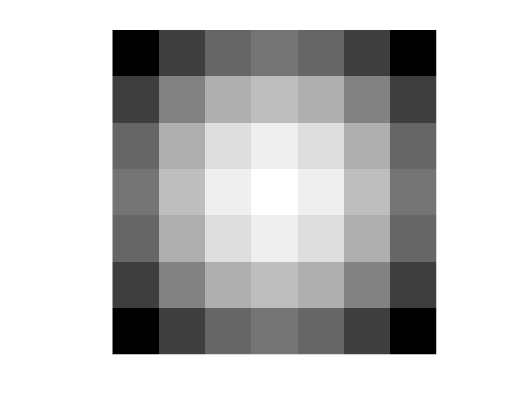

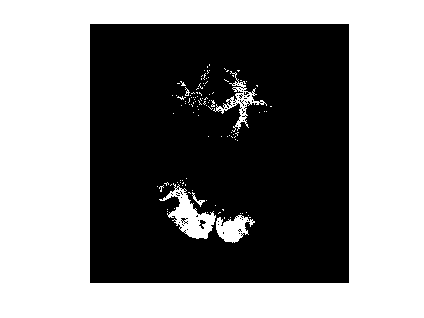

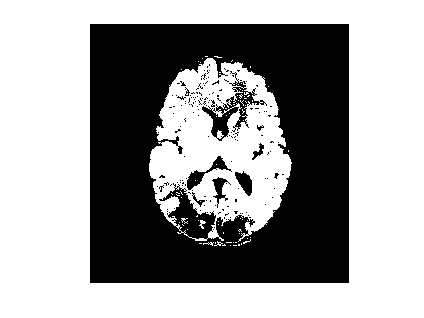

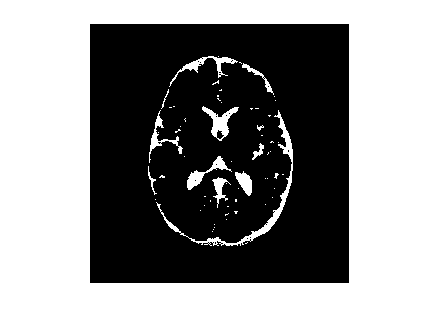


[sk, uijk, ck, bi, A, R, ck0, sk0, F] = computeFCM(insideBrain,q,K,imageMask);


display(strcat( ['Initial Class 1 Mean: ' num2str(ck0(1))]));

Initial Class 1 Mean: 0.8


display(strcat( ['Initial Class 2 Mean: ' num2str(ck0(2))]));

Initial Class 2 Mean: 0.5


display(strcat( ['Initial Class 3 Mean: ' num2str(ck0(3))]));

Initial Class 3 Mean: 0.2


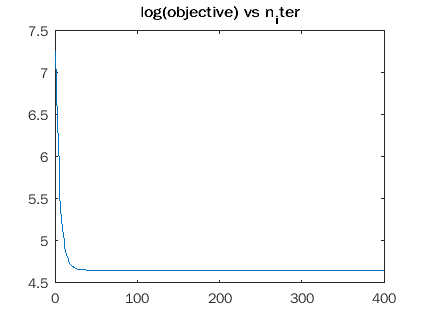


figure;plot(F);title('log(objective) vs n_iter');

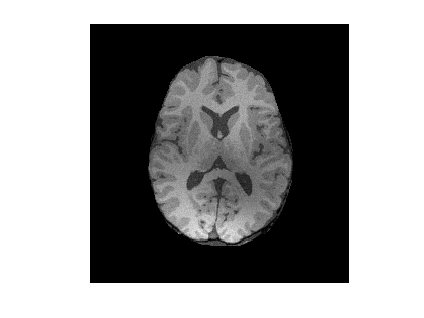

   
    figure; imshow(insideBrain);

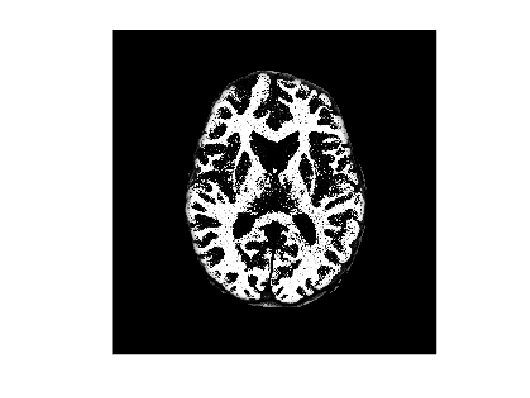

    imwrite(insideBrain,"corrupted.png");

%% Final Class Membershio Binary Images
    figure; imshow(uijk(:,:,1).*imageMask);

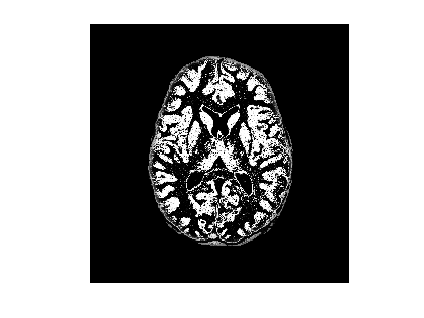

    imwrite(uijk(:,:,1),"uij12.png");
    figure; imshow(uijk(:,:,2).*imageMask);

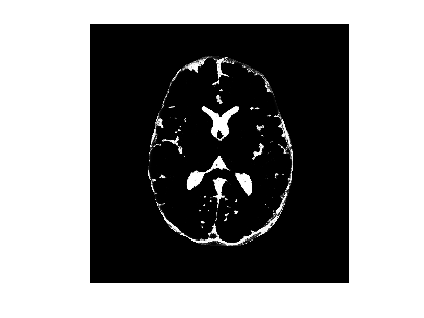

    imwrite(uijk(:,:,2),"uij22.png");
    figure; imshow(uijk(:,:,3).*imageMask);

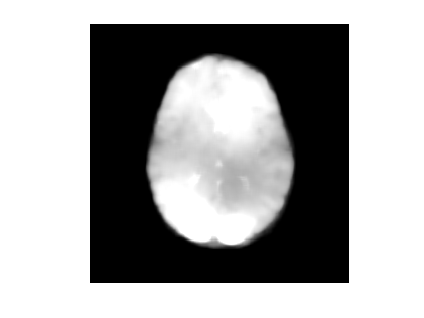

    imwrite(uijk(:,:,3),"uij32.png");

    figure; imshow(bi);

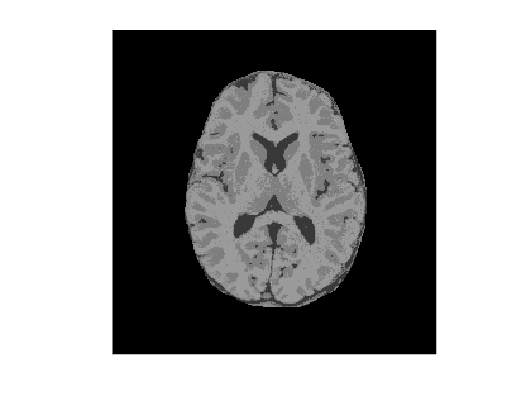

    imwrite(bi,"bias.png");
    figure; imshow(A.*imageMask);

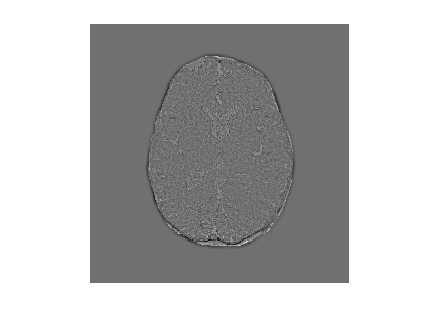

    imwrite(A.*imageMask,"biasRemoved.png");
    figure; imshow(R,[]);

    imwrite(R,"residual.png");

display(strcat( ['Final Class 1 Mean: ' num2str(ck(1))]));

Final Class 1 Mean: 0.60588


display(strcat( ['Final Class 2 Mean: ' num2str(ck(2))]));

Final Class 2 Mean: 0.49322


display(strcat( ['Final Class 3 Mean: ' num2str(ck(3))]));

Final Class 3 Mean: 0.21935


function [sk, uijk, ck, bi, A, R, ck0, ...
         sk0, F] = computeFCM(insideBrain,q,K,imageMask)

    [m, n] = size(insideBrain); 
    
    F = [];
    
    weights = fspecial('gaussian',7,5);
    % A = zeros(5,5);
    % sigma = 5;
    % weights = imgaussfilt(A,sigma);
    figure;imshow(weights,[]);
    imwrite(weights,"neighborMask.png");
    bi = 0.93*ones(m,n); % Do not touch
    
    [refImg,ck0] = kmeans(reshape(insideBrain,[m*n,1]),4);
    refImg =reshape(refImg,[m,n]);
    sk0=zeros(m,n,3);
    j=0;
    for i=1:4
        if i~=find(ck0<0.1)
            j=j+1;
            sk0(:,:,j)=(refImg==i)*ck0(i);
        end
    end
    
    image_max = max(max(insideBrain));
    image_min = min(min(insideBrain));
    range = image_max-image_min;
    uijk = zeros(m,n,K);
    ck = zeros(1,K);
    
    for i = 1:K  
       uijk(:,:,i) = (insideBrain >= image_min + range* (i-1)/K).*(insideBrain < image_min + range * i/K);
       ck(i) = image_min + range*(2*i-1)/(2*K);
    end
    
    uijk(:,:,K) = uijk(:,:,K) + (insideBrain == image_max);

    figure; imshow(uijk(:,:,3).*imageMask);
    imwrite(uijk(:,:,1),"uij11.png");
    figure; imshow(uijk(:,:,2).*imageMask);
    imwrite(uijk(:,:,2),"uij21.png");
    figure; imshow(uijk(:,:,1).*imageMask);
    imwrite(uijk(:,:,3),"uij31.png");
    
    % ck = ck0(ck0>0.1);

    % initialising class means
%     % initialising class means
%     flatten = sort(reshape(cropped_image.',1,[]));
%     k = 1;
%     while flatten(1,k) == 0
%         k = k + 1;
%     end
%     flatten = flatten(1,k:end);
%     plot(flatten);
%     l = length(flatten);
%     minnn = flatten(1,floor(l / 20));
%     maxxx = flatten(1,floor(19 * l / 20));
%     diff = (maxxx - minnn);
%     ck(3,1) = minnn + (diff * 0.2);
%     ck(2,1) = minnn + (diff * 0.5);
%     ck(1,1) = minnn + (diff * 0.8);
    ck = [0.8,0.5,0.2];
    % initialising class means
    ck0 = ck;
    
    sk = zeros(m,n,K);
    A = zeros(size(insideBrain,1),size(insideBrain,2));
    prev_objective = inf;
    flag = true;
    n_iter = 0;
    
    while(flag)
        n_iter = n_iter+1;    
        convSquared = conv2(bi.^2,weights,'same');
        convolution = conv2(bi,weights,'same');
        
        temp = zeros(m,n); 
        for i=1:K
            sk(:,:,i) = insideBrain.^2+ck(i)^2*convSquared-2*ck(i)*(insideBrain.*convolution);
            sk(:,:,i) = sk(:,:,i)+(sk(:,:,i)==0)*mean(mean(sk(:,:,i)));
            uijk(:,:,i) = sk(:,:,i).^(1/1-q)/100;
            temp = temp + uijk(:,:,i);
        end
    
        bias_num = zeros(m,n);
        bias_denom = zeros(m,n);
    
        for i=1:K
            uijk(:,:,i) = uijk(:,:,i)./temp;
            num =  sum(sum(uijk(:,:,i).^q.*insideBrain.*convolution));
            denom = sum(sum(uijk(:,:,i).^q.*convSquared));
            ck(i) = num/denom;
            bias_num = bias_num + uijk(:,:,i).^q*ck(i);
            bias_denom = bias_denom + uijk(:,:,i).^q*ck(i)^2;
        end
        bi = conv2(insideBrain.*bias_num,weights,'same')./conv2(bias_denom,weights,'same');
        
        temp=zeros(m,n);
        for i=1:K
            temp = temp + (uijk(:,:,i).^q).*sk(:,:,i);
        end
      
        objective = sum(sum(temp));
        if abs(objective - prev_objective)/abs(objective) < 0.01 && n_iter >= 400
            flag=0;     
        end
        F = [F log(objective)];
        prev_objective = objective;
    end
    
    for i=1:K
        A = A + uijk(:,:,i)*ck(i);
    end
        R = insideBrain - A.*bi;
end